# Regression: Basics

**Suggested Prework**

[MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html) – a free two-hour introductory tutorial to learn the essentials of MATLAB.

You can this script in a controls-only mode by using the **Hide code **  button, or view the code by using the **Output inline**    button on the **View** tab of the MATLAB toolstrip.

***Task:**** Click the ****Run**** button* to add the solution plots to your MATLAB search path.

 
addpath("regressSolnIm\")   % Ensure that this folder is in your current folder.

## What is Regression?

*Regression* refers to techniques for estimating the relationship between a dependent variable and one or more independent variables. In other words, it is a way to model a target (dependent) variable based on other (independent) variables. Regression is widely used for 

- explaining or quantifying the relationship between variables

- forecasting or making predictions from data

### Simple Linear Regression

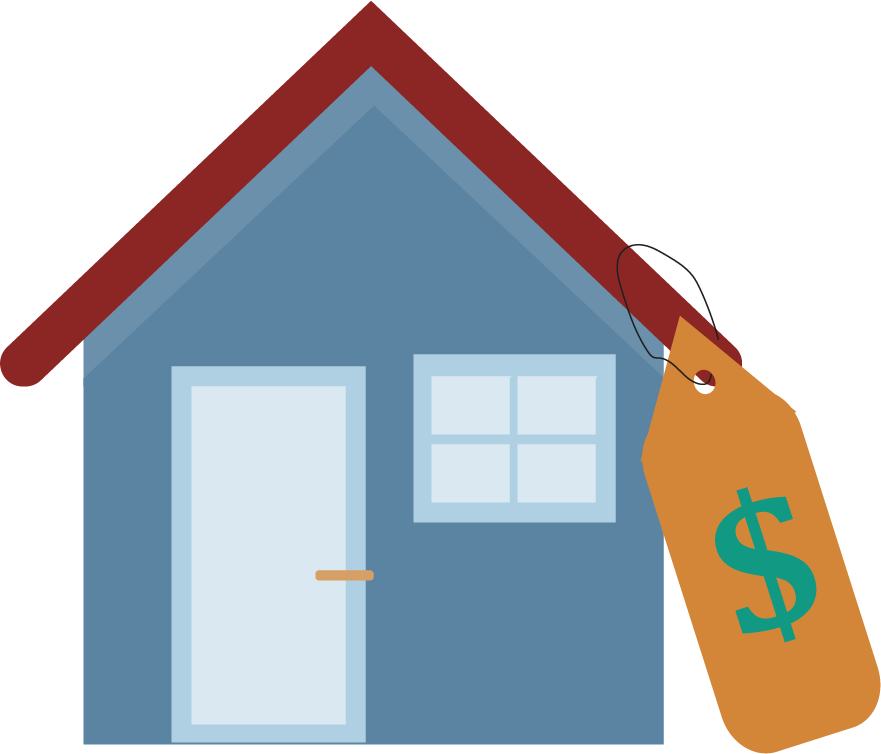 Suppose you want to estimate your home's current value on the market. Based on some experience, you believe that the square footage of a house might be a strong indicator of its value. So, you find the recent listings in the neighborhood to verify and model the relationship between the property's price and its square footage (area).

***Task:**** Click the button below to load and plot the house prices and the square footage as a scatter plot.*

 
load linearData.mat x y                     % Load data from a MAT file
figure;
scatter(x,y)                                % Plot the data points
xlabel("Area (sqft)")                       % Label the X axis
ylabel("Listed price (USD)")                % Label the Y axis
title("Listed price vs area of a house")    % Add a title

 **Reflect**

- Do you see a trend or pattern in the data?

Here, you have one dependent (price) and one independent variable (area) that appear to be linearly correlated. This is a simple linear regression problem, which uses a straight line to model the relationship between one dependent variable ($y$) and one independent variable ($x$):

                            
$$y\;=a_0 +a_1 x$$


***Task****: Click the ****Run**** button to plot a line with the slope *$a_1$ *and intercept *$a_0$*.*

load linearData.mat x y 
a1 =240;            % Set value for coefficient a1
a0 =160000;         % Set value for coefficient a0
 
figure("Position",[0 0 800 400]);          % Set up a figure for the plot
plotFit(x,y,[a1 a0],0);                    % Call the helper function to plot the polynomial fit and the data samples

  ***Try***

- *Use the sliders to set the slope (*$a_1$*)  and intercept (*$a_0$*) variables to generate different lines to model the relationship.*

- *Set the *`a1`* and *`a0`* values to find an approximate straight line to model or fit the data.*

 **Reflect**

- How easy was it to find the best coefficients?

- How did you determine that this line is a good fit for the data?

- Can you now estimate the price of a house with an area of 3800 sqft?

- Based on this model, can you predict the value of a house with an area of 10000 sqft? If yes, what assumptions are you making?

disp("Use the drop-down to reveal a likely solution")

#### Ordinary Least Squares

Your goal with regression is to find the best model describing the dependent variable as a function of the independent variable/s. One way to quantify the goodness of your model's fit is by calculating the sum of squared errors (SSE) between the actual and predicted values of the dependent variable.

                            
$$\textrm{SSE}=\;\sum_{i=1}^n {\left(y_i -\hat{y_i } \;\right)}^2$$


                            $y_i \;$            is the actual value of the dependent variable corresponding to the $i^{\textrm{th}}$ data sample out of $n$ total samples

                            ${\hat{y} }_i \;$            is the predicted value corresponding to the $i^{\textrm{th}}$ data sample out of $n$ total samples

***Task****: Click the ****Visualize errors**** button to see the error bars and display the sum of squared errors.*

load linearData.mat x y                     % Load data from a MAT file
a1 = 140;                                   % Set value for coefficient a1
a0 = 4000;                                  % Set value for coefficient a0
 
figure("Position",[0 0 800 400]);
plotFit(x,y,[a1 a0],1);                     % Visualize the errors

Substituing the straight line model for the predicted values, the goal of simple linear regression can now be formulated as the following minimization problem:

                        
$$\min_{a_0 ,a_1 } \sum_{i=1}^n {\left(y_i -\left(a_0 +a_1 x_i \right)\right)}^2$$


You can solve this analytically for $a_1$ and $a_0$ to get 

                        $a_1$=$\frac{\sum_{i=1}^n \left(x_i -\bar{x} \right)\left(y_i -\bar{y} \right)}{\sum_{i=1}^n {\left(x_i -\bar{x} \right)}^2 }$                           

                        
$$a_0 =\bar{y} -a_1 \bar{x}$$


where

                        $\bar{x}$ is the average of all $x_i$

                        $\bar{y}$ is the average of all $y_i$

                         $i$ indicates the individual data samples from a total of $n$ samples

**Exercise: **Check whether your manual selection of `a1` and `a0` matches the values you get from this analytical solution. You may choose to do this programmatically (in **Code Inline** mode) or by hand.

xbar = mean(x)
ybar = mean(y)

% Compute the values for a1 and a0 using the derived equations and the variables x, y, xbar, and ybar.
% ENTER CODE BELOW




### Multiple Linear Regression

 Consider another variable, in addition to the square footage or area of a house, that can help inform the house prices. For example, you can include the number of additional appliances and other special features in the house in your analysis.

***Task:**** Click the button below to load and plot the house prices, the square footage, and the number of special features as a scatter plot.*

 
load multivariateData.mat x1 x2 y                   % Load the data
figure;
scatter3(x1,x2,y,"o")                               % Plot the data points
xlabel("Additional house features (#)")             % Label the axes         
ylabel("Area (sqft)")
zlabel("Listed price (USD)")                    
title("House prices")                               % Add a title
view([-150 20])                                     % Adjust the line or sight

 **Reflect**

- Do you see a trend or pattern in the data?

Here, you have one dependent variable and two independent variables. You can perform a *multivariable* *regression*. If the model is linear in its coefficients, such as the equation of a plane, it is also called *multiple linear regression*.

                            
$$y=ax_1 +bx_2 +c{\mathrm{x}}_3 +\ldotp \ldotp \ldotp$$


This time, let us *standardize* the variables for the ease of finding the model coefficients; that is, center and scale every variable so that it has a mean of 0 and a standard deviation of 1.

***Task:**** Use the *[`normalize`](https://www.mathworks.com/help/matlab/ref/double.normalize.html)* function to standardize the variables *`x2`* and *`y`* in the edit fields given below. *

load multivariateData.mat x1 x2 y                     % Load the data
x1 =normalize(x1);                             % Standardize the data to have a mean of 0 and a standard deviation of 1
x2 =x2;
y = y;

***Task****: Click the ****Run**** button to generate a plane with coefficients defined below.*

a =-0.2;
b =0.2;
c =0;
 
figure("Position",[0 0 800 400]);                     % Set up a figure for the plot
plotMultiFit(x1,x2,y,[a b c]);                        % Call the helper function to plot the polynomial fit and the data samples

  ***Try***

- *Use the sliders to set the* $a$, $b$, and $c$ coefficient* values to generate different planes to model the linear relationship.*

- *Set the*` a`, `b`, and `c` values* to find the best plane to describe the data. This can be very challenging. To aid the process, use the plot tools such as ****Rotate ***  *and**** Pan***   *that appear in the top left of the figure window.*

 **Reflect**

- How easy or difficult was it to find the best coefficients to describe the model?

- How did you determine that the coefficients you chose created to a good fit?

disp("Use the drop-down to reveal a likely solution")

### Linear Regression with Nonlinearity in Data

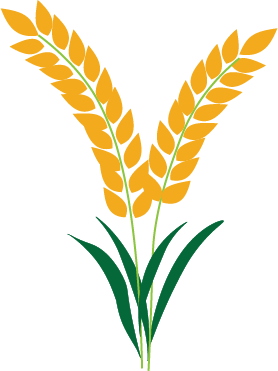Suppose you set up an experiment to model the effect of soil salinity near the roots of a crop on its overall yield. You control and measure the independent variable (salinity) and collect corresponding measurements for the dependent variable (crop yield). Next, you make a scatter plot to visually study the pattern and relationship between them.

***Task:**** Click the button below to load and plot the yield of a particular crop as a function of the soil salinity in the crop's root zone. *

 
load nonlinearData.mat x y                         % Load data from a MAT file
figure;
scatter(x,y)                                       % Plot the data points
xlabel("Salinity in the root zone (dS/m)")         % Label the X axis
ylabel("Crop yield (g/m^{2})")                     % Label the Y axis
title("Crop yield vs salinity")                    % Add a title

Salinity is reported in *deciSiemens per metre* ($\frac{\textrm{dS}}{m}$) by measuring electrical conductivity of the water or soil mixture.

 **Reflect**

- What kind of trend or pattern do you see in the data?

In the crop yield plot, there appears to be some curvature that you'd want to model. To do this, describe the relationship between a dependent and an independent variable with a polynomial, such that

                            
$$y\;=a_0 +a_1 x+a_2 x^2 +a_3 x^3 +a_4 x^4 +\;\ldotp \ldotp \ldotp$$


Even though this polynomial models the nonlinearity in the data, this model is linear in its unknown parameters—the coefficients ($a_0$,$a_1$,$a_2$, and so on). It is, therefore, considered a special case of the linear regression model. 

***Task****: Click the ****Run**** button to fit a polynomial of degree 2 to the crop yield data.*

load nonlinearData.mat x y                  % Load the data
a0 = 220;   
a1 =-10;
a2 =1.1;
 
figure("Position",[0 0 800 400])           % Set up a figure for the plot
plotFit(x,y,[a2 a1 a0],0);                  % Call the helper function to plot the polynomial fit and the data samples

  ***Try***

- *Use the sliders to set the* $a_0$, $a_1$, and $a_2$ coefficient* values to generate different curves to model the relationship.*

- *Set the values for *`a0`*, *`a1`*, and *`a2` *to find the best plane to describe the data.*

- *If you are using this script in ****Output inline**** mode, fit a polynomial of the third degree by including a new code variable *`a3`* for the coefficient *$a_3$*. (Remember to include *`a3`* in the third input to *`plotFit`*.)*

 **Reflect**

- How easy or difficult was it to find the best coefficients?

- How did you determine that the line was a good fit?

- Can you now predict the crop yield for a salinity of 6 dS/m?

- Does$y=a_0 +a_1 \sin \left(x\right)+a_2 x^2 +a_3 \log \left(x\right)$ describe a linear regression model between the variables $x$ and $y$?

disp("Use the drop-down to reveal a likely solution")

### Nonlinear Regression

There are numerous other approaches to model the nonlinear response of the crop yield to the soil salinity. In this section, you will apply and compare some other commonly-used models for estimating crop yield based on soil salinity. One commonly used model is a function describing an inverted S-shaped curve:

                            
$$y=\frac{Y_{\max } }{1+{\left(\frac{x}{a}\right)}^b }$$


                            $Y_{\max }$ is the maximum yield (where salinity has no effect on the yield)

Note that this model is nonlinear in its coefficients.

load nonlinearData.mat x y                  % Load data from a MAT file

For the ease of calculations, standardize the yield by dividing by the maximum yield.

                               
$$y_{\textrm{rel}} \;=\;\frac{y}{Y_{\max } }=\frac{1}{1+{\left(\frac{x}{a}\right)}^b }$$


***Task:**** Click the ****Run**** button to plot the crop yield data and the S-curve model.*

yRel = y./max(y);
mdl = @(x,a,b) 1./(1+(x./a).^b);
a = 1;
b = 3.2;
 

% Code to plot the data samples and the fitted model
figure("Position",[0 0 800 400])
plotNlinFit(x,yRel,a,b,mdl);

Models that are not linear in their unknown parameters are called *nonlinear* regression models. There isn't a small set of rules or general forms to describe all nonlinear models. They can take on many different forms. So, you must carefully choose a good functional form applicable to your data and problem. This often needs a lot of research and domain expertise.

**Try**

- *Use the sliders to set the* $a$ and $b$ parameter* values to model the relationship between *`x`* and *`y`*.*

- *Set the *`a `and b values* to find the best curve to describe the data.*

- *If you are using this script in ****Output inline**** mode, replace the model function in the text box to model one of the following nonlinear relationships:*

                       i)     $y_{\textrm{rel}} =\;e^{\textrm{ax}-b{\mathrm{x}}^2 }$

                       ii)     $y_{\textrm{rel}} =1-e^{a\left({\mathrm{e}}^{\textrm{bx}} \right)}$

             Try finding the model parameters $a$ and $b$ for these models. Note that these can be outside the range of the sliders provided.

**Reflect**

- What considerations might be needed to choose one of the nonlinear models for this data? (Look up some existing literature on the subject to help answer this question.)

disp("Use the drop-down to reveal a likely solution")

## Cost Function

So far in this module, you used slider controls to manually find the values of unknown parameters of the models, such as the coefficients of a polynomial. Regression analysis involves finding these unknown parameters more systematically. To do this, we minimize the "cost" associated with a poorly fitted model. You can use any measure of the goodness of fit as a *cost function*. This makes regression into an optimization problem essentially. The goal is to minimize the cost function to estimate the model's unknown parameters.

In a previous section, you used the sum of squared errors (SSE)  to measure the goodness of fit. A related measure is the mean squared error (MSE)—an average of squared prediction errors for a given number of sample data points. 

                            
$$\textrm{MSE}=\frac{1}{n}\sum_{i=1}^n {\left(y_i -{\hat{y} }_i \right)}^2$$


                            $y_i \;$            is the actual value of the dependent variable corresponding to the $i^{\textrm{th}}$ data sample out of $n$ total samples

                            ${\hat{y} }_i \;$            is the predicted value corresponding to the $i^{\textrm{th}}$ data sample out of $n$ total samples

Next, formalize the objective of regression by using the mean squared error as a cost function.

**Cost function: **

                           
$$J\left(\theta_1 ,\theta_2 ,\ldotp \ldotp \ldotp \right)=\;\frac{1}{n}\sum_{i=1}^n {\left(y_i -f\left(x_i ,\theta_1 ,\theta_2 ,\ldotp \ldotp \ldotp \right)\right)}^2$$


                            $\theta_1 ,\theta_2 ,\ldotp \ldotp \ldotp$        are the model parameters

                             $f$                  is the function describing the model; that is, the relationship between the dependent and independent variables 

**Objective**:

                            
$$\min_{\theta_1 ,\theta_2 ,\ldotp \ldotp \ldotp } \sum_{i=1}^n J\left(\theta_1 ,\theta_2 ,\ldotp \ldotp \ldotp \right)$$
 

In the Ordinary Least Squares approach, we minimized the sum of squared errors (SSE) to solve for the parameters ($a_1$ and $a_0$) analytically. Such analytical solutions cannot be easily found for the more complex models, or they might not even exist. So, you iteratively search for the parameters in a way that makes the cost smaller!

load linearData2.mat x y

***Task:**** Fit a linear regression model to predict *`y`* by setting the coefficients *`a1`* and *`a0`*. Use the displayed MSE value as a guide to **iteratively** improve your selection of coefficients.*

a1 =1.4;
a0 =0.9;
 
figure("Position",[0 0 800 400])
yhat = plotFit(x,y,[a1 a0],0);                             % Call the helper function to plot the linear fit and the data samples
MSE = mean((y-yhat).^2);                                   % Calculate the mean squared error

% Annotate plot
text(-1,6,"MSE = " + MSE,"FontSize",14)                    % Include the MSE on the plot for reference to update the fit

 **Reflect**

- Did the value of MSE in each attempt help guide your search? How?

- What other possible cost functions can you think of?

disp("Use the dropdown to reveal a likely solution")

## Gradient Descent

Gradient descent is an algorithmic solution for iteratively minimizing the cost function and estimating the unknown model parameters. As the name implies, this algorithm works by computing the cost function's *gradients*. These are the partial derivatives of the cost function with respect to each model parameter. The parameters are then updated in each iteration by subtracting the respective partial derivatives from their current values. 

load linearData2.mat x y

***Task:**** Click the ****Run**** button to visualize how gradient descent works.*

learningRate = 0.07;            
numSteps = 30;
 

figure("Position",[0 0 800 600])                                     % Set up a figure for the plot                       
[a1,a0,mse] = gradientDescent(x,y,numSteps,learningRate);            % Call the helper function to perform gradient descent and visualize the plots

Here, we consider a simple case with only two coefficients. Visualize the relationship between the MSE and the model coefficients $a_0$ and $a_1$ in a 3-D plot. This plot resembles a valley with one minimum (red dot). Remember, our goal is to reach that minimum. Starting at an initial point (for instance, at one of the top corners), the gradient descent algorithm calculates the direction to go down the valley. This is done in several steps or over many *iterations*. The step size is described by a [*hyperparameter*](https://www.mathworks.com/support/search.html/videos/applied-machine-learning-part-3-hyperparameter-optimization-1547849445386.html?fq=asset_type_name:video%20category:stats/regression-and-anova&page=1) called the *learning rate*.

  ***Try ***

- *Use the sliders to try different learning rates and number of iterations. Then click the ****Run**** button to observe gradient descent in action.*

- *Set the *`learningRate`* to 0.01.*

- *To combat the low learning rate, increase *`numSteps`* to 80.*

- *Set the *`learningRate`* to 0.25 and *`numSteps`* to 30.*

- *Increase the *`learningRate`* to 0.35 and *`numSteps`* to 50*`.`

 **Reflect**

- What happens when you choose a low learning rate?

- What happens when you choose a high learning rate?

- How does the number of steps affect the outcome?

With MSE as the cost function and a simple linear regression model, these are the gradient equations:

                             
$$\frac{d\left(f\right)}{da_1 }=\frac{2\alpha }{n}\sum_{i=1}^n x_i \left({\hat{y} }_i -y_i \right)$$
                    
$$\frac{d\left(f\right)}{da_0 }=\frac{2\alpha }{n}\sum_{i=1}^n \left({\hat{y} }_i -y_i \right)$$


                            $\alpha$ is the learning rate.

## Practice Problem

### Electricity load forecasting

The amount of electricity required to support an electrical grid is also referred to as the ***load*** on the grid, and it varies significantly over a day. Having a forecast of the electrical load is vital to several entities. It helps utility companies plan how much electricity their power plants will need to produce. It also supports energy traders to gain insight into upcoming market dynamics.Below is an example profile of the electrical load on the grid in New York City.

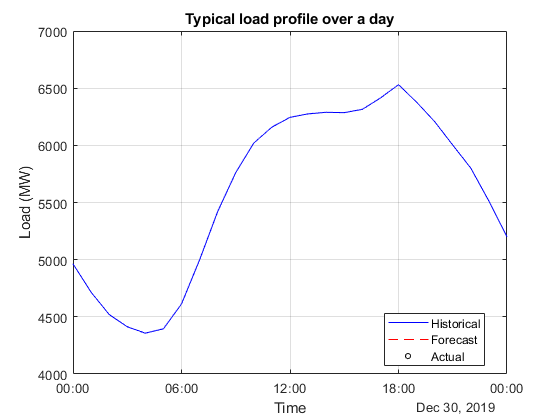

**NOTE: **This section requires you to download external data from [New York ISO](http://mis.nyiso.com/public/) and take approximately 1-5 minutes (depending on your internet connection). The script `electricityLoadDataML.mlx` included with this module downloads, formats, and saves the data.

***Task:**** Click the ****Open script to load data**** button to open *`electricityLoadData.mlx`*. Set the parameters in this script to download electricity data for the start and end dates given below.*

**          Start date: **`2015-Jan-01`       **         End date:** `2020-Dec-31`

edit electricityLoadData.mlx
 

As a first step, try simple linear regression to predict future electrical load. You will use only the electrical load as a dependent variable and time as an independent variable.

***Task: ****Select a time granularity for electricity data. Click the ****Run**** button to perform linear regression with time as the independent variable.*

load nyiso_cleaned.mat nyiso

% Select granularity of electricity data
tt = retime(nyiso,"daily","mean")       
 

Use the function [`fitlm`](https://www.mathworks.com/help/stats/fitlm.html) to fit a linear regression model.

dateNos = datenum(tt.Date)                       % Convert the datetime variable into numeric values to apply regression.
mdl = fitlm(dateNos,tt.HUDVL);                   % Fit a linear regression model

% Display model parameters and the MSE
coeffs = mdl.Coefficients
MSE = mdl.MSE

Use [`plot`](https://www.mathworks.com/help/releases/R2020b/stats/linearmodel.plot.html#responsive_offcanvas) with the fitted model to visualize a scatter plot of the data and the line fit.

plot(mdl)

% Format the x-axis labels into date and time values.
xticklabels(datestr(xticks))
xtickangle(30)

   ***Try***

- *Use the dropdown menu to choose the granularity of the load data.*

- *Observe the error in *`mse`* after clicking ****Run****.*

   **Reflect**

- When does the highest error occur?

- When does the lowest error occur?

- What granularity is the linear regression better for? What does that indicate?

Once you have a model, you can use the [predict](https://www.mathworks.com/help/stats/linearmodel.predict.html) function to compute the dependent variable's value for any given independent variable values.

% Choose a date to make a prediction for the electrical load
predDay = 21;
predMonth = 8;
predYear =2021;
 

predDate = datetime(predYear,predMonth,predDay);                                % Convert the chosen data, month, and year into a MATLAB datetime type
predLoad = predict(mdl,datenum(predDate));                                      % Use the fitted model to predict for the chosen data

disp("Your model predicts a load of " + predLoad + "MW for "+ datestr(predDate))   % Display the result from prediction

Although you did not achieve a very accurate forecast for high-granularity data in the previous section, can you use the results to model the long-term trend?

 ***Quiz: ****Study the results from the task above and select all that apply.*

**A. The electricity load in Hudson Valley is likely to increase in 2021 compared to 2020.**

increase = false;

**B.** **The electricity load in Hudson Valley is likely to decrease in 2021 compared to 2020.**

decrease = false;

disp("Use the dropdown to reveal answer")

 **Reflect**

- Can you think of any other factors or variables which might influence the electricity load at a given instance?

## 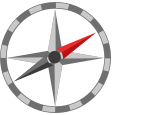Further Exploration

### Multiple predictors for short-term electricity load forecast

As you may have noticed in the practice problem, with `Date` as your only independent variable, the electricity load forecast does not tend to be very accurate at an hourly granularity. 

Independent variables are also referred to as *explanatory variables* or *predictor* *variables****,*** or simply *predictors*. A different independent variable or even a combination of variables can improve our ability to model the data and make predictions. Here, you are given a function `getMultiPredictors` that generates three different predictors for the hourly electricity load (MW). 

***a. Task:**** Click ****Generate Predictors**** to run this section to see the predictors.*

load nyiso_cleaned.mat nyiso                                  % Load data from the saved MAT file
[hourlyLoad,dates,predictors] = getMultiPredictors(nyiso);    % Use helper function to generate some additional predictors from the data
 

disp(predictors)

 **Reflect**

Observe the `predictors` variable displayed above. 

- Do you notice a pattern to help identify what physical quantities these three predictors represent? **Hint:** Scroll to see more rows of data, and compare each column with the `hourlyLoad` values.

- How far into the future will our model will be able to forecast given this selection of predictors? Why?

***b. Task: ***Click **Fit Linear Regression** to fit a multiple linear regression model to the data in `predictors` to predict the response variable `hourlyLoad.`

 

% Fit the linear regression model.
mdl = fitlm(predictors,hourlyLoad);
coeffs = mdl.Coefficients
MSE = mdl.MSE

% Use the the fitted model to get predicted hourly load values and compare them with the actual values.
predLoad = predict(mdl,predictors);

% Plot the actual and predicted load.
figure
plot(dates,hourlyLoad,"o","MarkerSize",4)
hold on
plot(dates,predLoad,"r")
hold off

% Label the plot
legend("Actual","Predicted")
xlabel("Time")
ylabel("Hourly Load (MW)")
title("Electricity Load: Multiple Linear Regression")

***c. Task: ****Zoom into a small window of time by setting the axis limits using the sliders given below.*

% Zoom into a small window of time by setting the axis limits
xlim([datetime(2020,1,12,"TimeZone","America/New_York")... % set lower limit for day of month
    datetime(2020,1,18,"TimeZone","America/New_York")])  % set upper limit for day of month

 **Reflect**

- By visually analyzing the data and the model predictions, do you find this an acceptable model? 

## Helper functions

Function to plot a one-variable linear regression of any degree.

function yhat = plotFit(x,y,A,errorFlag)

% Prepare data and compute the model predictions
powers = length(A)-1:-1:0;
X = x'.^powers;
yhat = A*X';

% Plot
plot(x,y,"o");
dispLine = sprintf("\nLine fit \n" + "y = " + join(A + ["x^{"+string(powers(1:end-1))+"}",""] ," + "),"Interpreter","tex");
xlim([min(x)-0.5,max(x)+0.5]);
ylim([min(y)-0.5,max(y)+0.5]);
hold on
fplot(@(x)A*(x'.^powers)',"LineWidth",1.5);
legend("Data samples",dispLine,"Location","eastoutside")
hold off
xlabel("x")
ylabel("y")
title("Linear model")

if errorFlag
    hold on
    dispSSE = sprintf("\nErrors \nSSE = %12g",sum(yhat-y).^2);
    errorbar(x,y,min(yhat-y,0),max(yhat-y,0),".","vertical","DisplayName",dispSSE,"Color",[0.8 0.6 0]);
    hold off
end

end

Function to plot a plane fit based on its coefficients.

function yhat = plotMultiFit(x1,x2,y,coeffs)

% Split the coefficients into individual variables and estimate y.
[a,b,c] = deal(coeffs(1),coeffs(2),coeffs(3));
yhat = a.*x1 + b.*x2 + c;

% Plot
scatter3(x1,x2,y);
xlim([min(x1)-0.1,max(x1)+0.1]);
ylim([min(x2)-0.1,max(x2)+0.1]);
zlim([min(y)-0.1,max(y)+0.1]);
[X1,X2] = meshgrid(xlim,ylim);
hold on
surf(X1,X2,a.*X1 + b.*X2 + c,"FaceAlpha", 0.4,"FaceColor",[1 0.5 0.5],"EdgeColor","none");
hold off
% Annotate
title("Multiple linear model")
dispPlane = sprintf("\nPlane fit"+"\ny = " + a + "x_{1} + " + b + "x_{2} + " + c);
legend("Data samples",dispPlane,"Location","eastoutside");
view([-150 20])
xlabel('x_{1}'), ylabel('x_{2}'), zlabel("y")

end

Function to plot a nonlinear fit based on model function (mdl) and two parameters (a,b).

function plotNlinFit(x,yRel,a,b,mdl)
plot(x,yRel,"o");                                       % Plot the data samples
hold on
fplot(@(x)mdl(x,a,b))                                   % Plot the fitted model
hold off
title("Nonlinear model")                                % Add title
xlabel("Salinity in the root zone (dS/m)")              % Label the X axis
ylabel("Relative crop yield")                           % Label the Y axis
str = compose("$y = \\frac {1}{1+(\\frac {x}{%2g})^{%2g}}$",a,b);
legend("Data samples",newline + "S-curve fit","Interpreter","latex")
text(10.5,0.7,str,"Interpreter","latex","FontSize",20);
end

Function to perform and visualize gradient descent using mean-squared error cost for linear regression.

function [a1,a0,mse] = gradientDescent(x,y,steps,learningRate)

% Prepare variables for visualizing the surface plot of cost function
[M,B] = meshgrid(-10:0.1:10,-10:0.1:10);
cost = arrayfun(@(m,b)costFunc(m,b,x,y),M,B);

% Initialize loop
a1 = 7;                       % initial slope value
a0 = 7;                       % initial intercept value
n = length(x);                % total number of data points
mse = costFunc(a1,a0,x,y);    % compute initial MSE
r = logspace(-0.5,0,steps);  % red color intensities for the plots

% Plot three different visualizations
T = tiledlayout(2,2,"TileSpacing","compact","Padding","compact");

% Plot 1: surface
nexttile(T,1)
surf(M,B,cost,"EdgeColor","none")
hold on
plot3(a1,a0,mse,"*","Color",[0 0 0]);
hold off
colormap(parula(30))
view([-16 33])
xlabel("a1"), ylabel("a0"), zlabel("Cost (MSE)")

% Plot 2: contour
nexttile(T,2)
contour(M,B,cost,30,"LineWidth",2)
hold on
plot(a1,a0,"*","Color",[0 0 0],"MarkerSize",8)
hold off
xlabel("a1"), ylabel("a0")

% Plot 3: line fit
title(T,"Gradient descent")
nexttile(T,[1,2])
plot(x,y,"o")
hold on
fitLine = plot(xlim,a1.*xlim+a0,"-","LineWidth",1.5,"Color",[0 0 0]);
hold off
ylim([-10,10]), xlabel("x"), ylabel("y")


for step=1:steps

    % Compute gradient descent
    pause(0.02)
    yhat = a1*x + a0;
    diff = yhat - y;
    da1 = learningRate * sum(diff .* x) * 2 / n;
    da0 = learningRate * sum(diff) * 2 / n;
    a1 = a1 - da1;
    a0 = a0 - da0;
    mse = costFunc(a1,a0,x,y);

    % Plot new iteration data over the existing plots
    nexttile(T,1)
    hold on
    plot3(a1,a0,mse,"*","Color",[r(step) 0 0]);
    hold off

    nexttile(T,2)
    hold on
    plot(a1,a0,"*","Color",[r(step) 0 0],"MarkerSize",8)
    hold off

    nexttile(T,3)
    fitLine.YData = a1*xlim+a0;
    fitLine.Color = [r(step) 0 0];
    title("a1 = "+a1 + ", a0 = "+a0, "MSE = "+mse)

end
end

Function to compute mean-squared error for a line fit.

function mse = costFunc(m,b,x,y)
yhat = m*x+b;
mse = sum((yhat-y).^2)/length(x);
end

Generate multiple predictor variables for hourly load.

function [hourlyLoad,dates,predictors] = getMultiPredictors(nyiso)
tt = retime(nyiso,"hourly","mean");
pred = tt.HUDVL;
N = [7 24 168];
predictors = [[nan(N(1),1); pred(1:end-N(1))],[nan(N(2),1); pred(1:end-N(2))],[nan(N(3),1); pred(1:end-N(3))]];
hourlyLoad = tt.HUDVL;
dates = tt.Date;
end
